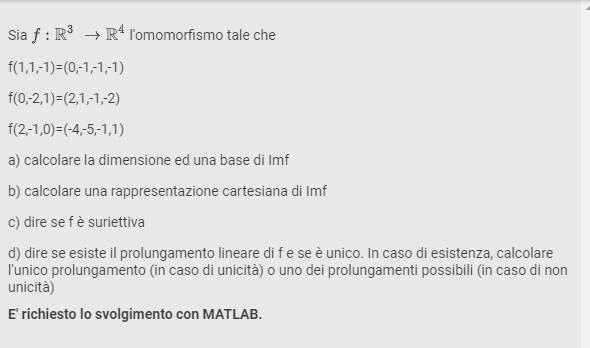

v1 = [1 1 -1]

v1 =      1     1    -1


v2 = [0 -2 1]

v2 =      0    -2     1


v3 = [2 -1 0]

v3 =      2    -1     0


fv1 = [0 -1 -1 -1]

fv1 =      0    -1    -1    -1


fv2 = [2 1 -1 -2]

fv2 =      2     1    -1    -2


fv3 = [-4 -5 -1 1]

fv3 =     -4    -5    -1     1


**a) Calcolare la dimensione ed una base di Imf**

Per prima cosa verifico se i vettori v_n formano una base di R^3:

A = [v1 ; v2 ; v3]

A =      1     1    -1
     0    -2     1
     2    -1     0


rank(A)

ans = 3

B3 = A

B3 =      1     1    -1
     0    -2     1
     2    -1     0


I vettori costituiscono una base. La matrice caratteristica associata all'omomorfismo ha per colonne le componenti delle immagini dei vettori della base rispetto alle basi considerate.

Le colonne di tale matrice generano l'immagine  dell'applicazione lineare. Affinché costituiscano una base devono essere linearmente indipendenti. Considero la trasposta di M:

M= [fv1 ; fv2 ;fv3]

M =      0    -1    -1    -1
     2     1    -1    -2
    -4    -5    -1     1


Mt = transpose(M)

Mt =      0     2    -4
    -1     1    -5
    -1    -1    -1
    -1    -2     1


rank(M)

ans = 2

La matrice ha rango 2, una base dell'immagine é formata quindi da 2 vettori. Ne scelgo 2 linearmente indipendenti. Verifico che effettivamente lo siano:

BImf = [fv1 ; fv2]

BImf =      0    -1    -1    -1
     2     1    -1    -2


rank(BImf)

ans = 2

**b) Calcolare una rappresentazione cartesiana di Imf**

Per trovare una rappresentazione cartesiana considero il vettore generico dello spazio vettoriale in questione, il quale deve essere generato dalla base precedentemente trovato, pertanto linearmente indipendente. Considero quindi la relativa matrice:

syms x y z t
w = [x y z t]

$$w = \left(\begin{array}{cccc} x & y & z & t \end{array}\right)$$


L = [BImf ; w]

$$L = \left(\begin{array}{cccc} 0 & -1 & -1 & -1\\ 2 & 1 & -1 & -2\\ x & y & z & t \end{array}\right)$$

Riduco a scalini:

temp = L(2,:) 

$$temp = \left(\begin{array}{cccc} 2 & 1 & -1 & -2 \end{array}\right)$$

L(2,:) = L(1,:) 

$$L = \left(\begin{array}{cccc} 0 & -1 & -1 & -1\\ 0 & -1 & -1 & -1\\ x & y & z & t \end{array}\right)$$

L(1,:) = temp

$$L = \left(\begin{array}{cccc} 2 & 1 & -1 & -2\\ 0 & -1 & -1 & -1\\ x & y & z & t \end{array}\right)$$


L(3,:)=2*L(3,:) - x*L(1,:)

$$L = \left(\begin{array}{cccc} 2 & 1 & -1 & -2\\ 0 & -1 & -1 & -1\\ 0 & 2\,y-x & x+2\,z & 2\,t+2\,x \end{array}\right)$$

L(3,:)=L(3,:) + (2*y-x)*L(2,:)

$$L = \left(\begin{array}{cccc} 2 & 1 & -1 & -2\\ 0 & -1 & -1 & -1\\ 0 & 0 & 2\,x-2\,y+2\,z & 2\,t+3\,x-2\,y \end{array}\right)$$

L'ultima riga deve essere nulla in quanto linearmente dipendente:


$$\begin{cases}

2x-2y+2z=0 \\
2t+3x-2y=0

\end{cases}$$


Il sistema costituisce una rappresentazione cartesiana dell'immagine dell'omomorfismo.

**c) Dire se é suriettiva**

Non é suriettiva in quanto $\dim \;\mathrm{Imf}\;\not= \;\dim \;R^4$.

**d) dire se esiste il prolungamento lineare, in caso calcolarlo**

Il prolungamento lineare esiste ed é unico in quanto la base dello spazio vettoriale é giá completa. Considero la base di R^3 precedentemente verificata. Tale base genera tutti i vettori dello spazio vettoriale, per cui un generico vettore puó essere scritto come combinazione lineare:

syms a b c
xyz = a*v1 + b*v2 +c*v3

$$xyz = \left(\begin{array}{ccc} a+2\,c & a-2\,b-c & b-a \end{array}\right)$$

Da cui si ottiene il sistema lineare:


$$\begin{cases}

a+2c = x \\ a-2b =y \\ b-a =z
\end{cases}$$


Risolvo il sistema, considero la matrice associata per ottenere un sistema minimale equivalente:

Z = [ 1 0 2 x ; 1 -2 0 y ; -1 1 0 z]

$$Z = \left(\begin{array}{cccc} 1 & 0 & 2 & x\\ 1 & -2 & 0 & y\\ -1 & 1 & 0 & z \end{array}\right)$$

Z(2,:)=Z(2,:)-Z(1,:)

$$Z = \left(\begin{array}{cccc} 1 & 0 & 2 & x\\ 0 & -2 & -2 & y-x\\ -1 & 1 & 0 & z \end{array}\right)$$

Z(3,:)=Z(3,:)+Z(1,:)

$$Z = \left(\begin{array}{cccc} 1 & 0 & 2 & x\\ 0 & -2 & -2 & y-x\\ 0 & 1 & 2 & x+z \end{array}\right)$$

Z(3,:)=2*Z(3,:)+Z(2,:)

$$Z = \left(\begin{array}{cccc} 1 & 0 & 2 & x\\ 0 & -2 & -2 & y-x\\ 0 & 0 & 2 & x+y+2\,z \end{array}\right)$$

Da cui il sistema:


$$\begin{cases}
a + 2c =x \\
-2b-2c =y-x \\
c =x+y+2z

\end{cases}

\to

\begin{cases}
a = -x-2y-4z \\
b=-x-2y-3z \\
c =x+y+2z

\end{cases}$$


a = -x-2*y-4*z

$$a = -x-2\,y-4\,z$$

b = -x -2*y -3*z

$$b = -x-2\,y-3\,z$$

c = x + y+2*z

$$c = x+y+2\,z$$

Cb = [a b c]

$$Cb = \left(\begin{array}{ccc} -x-2\,y-4\,z & -x-2\,y-3\,z & x+y+2\,z \end{array}\right)$$

Che rappresentano le componenti rispetto alla base di R^3 considerata. Sostituendo nella combinazione lineare si ha:

xyz = a*v1 + b*v2 +c*v3

$$xyz = \left(\begin{array}{ccc} x & y & z \end{array}\right)$$

Da cui il prolungamento lineare:

f_xyz = a*fv1 + b*fv2 + c*fv3

$$f\_xyz = \left(\begin{array}{cccc} -6\,x-8\,y-14\,z & -5\,x-5\,y-9\,z & x+3\,y+5\,z & 4\,x+7\,y+12\,z \end{array}\right)$$

Il prolungamento é unico